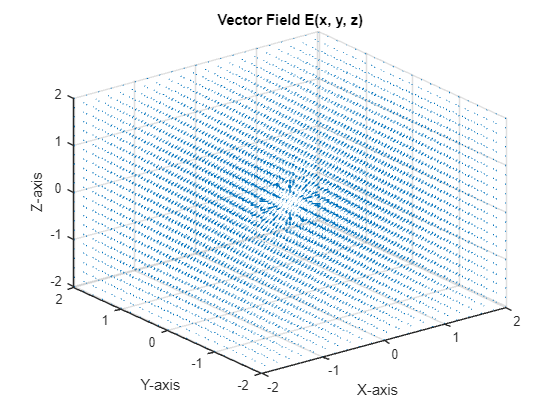

% 🌟✨🖥️ MATLAB Code by Seyed Mohammad Sajadi 🖥️✨🌟
% Student Number: 402448040

% Define the vector field function
E_x = @(x, y, z) x./(x.^2 + y.^2 + z.^2);
E_y = @(x, y, z) y./(x.^2 + y.^2 + z.^2);
E_z = @(x, y, z) z./(x.^2 + y.^2 + z.^2);

% Define the grid
[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);

% Calculate the vector field values
U = E_x(x, y, z);
V = E_y(x, y, z);
W = E_z(x, y, z);

% Plot the vector field using quiver3
figure;
quiver3(x, y, z, U, V, W);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Vector Field E(x, y, z)');
axis tight;
grid on;

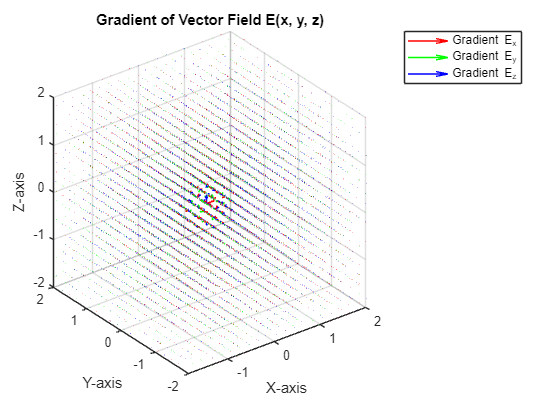

% Define the vector field function
E_x = @(x, y, z) x./(x.^2 + y.^2 + z.^2);
E_y = @(x, y, z) y./(x.^2 + y.^2 + z.^2);
E_z = @(x, y, z) z./(x.^2 + y.^2 + z.^2);

% Define the grid
[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);

% Calculate the gradient of each component
[Ex_dx, Ex_dy, Ex_dz] = gradient(E_x(x, y, z), 0.2, 0.2, 0.2);
[Ey_dx, Ey_dy, Ey_dz] = gradient(E_y(x, y, z), 0.2, 0.2, 0.2);
[Ez_dx, Ez_dy, Ez_dz] = gradient(E_z(x, y, z), 0.2, 0.2, 0.2);

% Plot the gradient vectors using quiver3
figure;
quiver3(x, y, z, Ex_dx, Ex_dy, Ex_dz, 'r');
hold on;
quiver3(x, y, z, Ey_dx, Ey_dy, Ey_dz, 'g');
quiver3(x, y, z, Ez_dx, Ez_dy, Ez_dz, 'b');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Gradient of Vector Field E(x, y, z)');
axis tight;
grid on;
legend('Gradient E_x', 'Gradient E_y', 'Gradient E_z');
hold off;

%% Given
f = @(x,y,z) [-2*y; x; z/10]; % anonymous fx: f(x,y)
xi = -2; xf = 2; yi = -1; yf = 1; zi = 0; zf = 3; n = 5; % independent variables: initial and final values, and number of elements
%% Calculations
    % x, y, z, wx, wy, and wz values
        X = linspace(xi,xf,n); Y = linspace(yi,yf,n); Z = linspace(zi,zf,n); [x,y,z] = meshgrid(X,Y,Z); % x, y, and z 3D matrices
        w = f(x,y,z); wx = w(1:n,:,:); wy = w(n+1:2*n,:,:); wz = w(2*n+1:3*n,:,:); % w = f(x,y,z) and components 3D matrices
    % magnitude of w
        wmag = zeros(n,n,n);
        for i = 1:n
            for ii = 1:n
                for iii = 1:n
                    wmag(i,ii,iii) = norm([wx(i,ii,iii) wy(i,ii,iii) wz(i,ii,iii)]); % w vector function magnitude
                end
            end
        end
    % divergence values
        % analytical
            % partial derivatives
                sf = sym(f); nf = numel(sf); st = func2str(f); % symbolic variables
                st1 = find(st=='('); st1 = st1(1); stend = find(st==')'); stend = stend(1);
                stmid = find(st==','); stmid = stmid(stmid<stend);
                sv = str2sym(['[' st(st1+1:stend-1) ']']);
                pd = cell(nf,1); pdf = sym(zeros(nf,1));
                for i = 1:nf
                    pd{i,1} = diff(sf,sv(i)); % all partial derivatives
                    pdf(i,1) = pd{i}(i); % selected [dfx/dx; dfy/dy; dfz/dz]
                end
                pd = [pd{:}]'; pd = reshape(pd,nf^2,1); % all [dfx/dx; dfx/dy; dfx/dz; dfy/dx; dfy/dy; dfy/dz; dfz/dx; dfz/dy; dfz/dz;]
                F1 = GETVAL(pdf,x,y,z,n,nf); % cell values
            divw = F1{1}+F1{2}+F1{3}; % analytical divergence of w
        % numerical
            divwn = divergence(x,y,z,wx,wy,wz); % numerical divergence of w
    % curl values
        % analytical
                F = GETVAL(pd,x,y,z,n,nf^2); % cell values
                curlwx = F{8}-F{6}; curlwy = F{3}-F{7}; curlwz = F{4}-F{2}; % components
            curlw = [curlwx; curlwy; curlwz]; % analytical curl of w
        % numerical
                [curlwxn,curlwyn,curlwzn,cavn] = curl(x,y,z,wx,wy,wz);

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.

            curlwn = [curlwxn; curlwyn; curlwzn]; % numerical curl of w
%% Display Results
    % function
        % isosurface
            subplot(2,2,1); view(3);
            for i = 1:n*n*n
                isosurface(x,y,z,wmag,wmag(i)); % isosurface plot
            end
            grid('on'); xlabel('x'); ylabel('y'); zlabel('z'); title('Magnitude of w Colorbar'); colorbar;
        % vectors using plot3 
            M = max(max(max(w))); k = 2.5; hold('on'); view(3);
            for i = 1:n^3
                plot3([0 wx(i)]/(k*M)+x(i),[0 wy(i)]/(k*M)+y(i),[0 wz(i)]/(k*M)+z(i),'k-'); % line
                plot3(wx(i)/(k*M)+x(i),wy(i)/(k*M)+y(i),wz(i)/(k*M)+z(i),'>k','markersize',3,'markerfacecolor','r'); % end point marker
            end
            axis([xi+0.15*xi xf+0.15*xf yi+0.15*yi yf+0.15*yf zi+0.15*zi zf+0.15*zf]); hold('off');
        % vectors using quiver3
            subplot(2,2,2); quiver3(x,y,z,wx,wy,wz,'linewidth',1,'color','k'); % quiver 3D plot of w
            xlabel('x'); ylabel('y'); zlabel('z'); title('w = f(x,y,z) = [-2y; x; z/10] using Quiver 3D Plot');
    % divergence of the function
        subplot(2,2,3); quiver3(x,y,z,wx,wy,wz,'linewidth',1,'color','k'); hold('on'); % quiver 3D plot of w
        xs = [xi 0 xf]; ys = yf; zs = zi; % slice positions
        S = slice(x,y,z,divw,xs,ys,zs); S(1).FaceAlpha = 0.5; S(2).FaceAlpha = 0.5; % slice plot analytical divergence of w
        colormap('jet'); colorbar; shading('interp'); camlight; set([S(1) S(2)],'ambientstrength',0.6);
        xlabel('x'); ylabel('y'); zlabel('z'); title('Divergence of w','color',[1 0 0]); grid('on'); hold('off');
    % curl of the function
        subplot(2,2,4); Qf = quiver3(x,y,z,wx,wy,wz,'linewidth',1,'color','k'); hold('on'); % quiver 3D plot of w
        Qc = quiver3(x,y,z,curlwx,curlwy,curlwz,'linewidth',2,'color','r'); % quiver 3D plot of the curl of w
        title('Vectors: Curl of w','color','r'); xlabel('x'); ylabel('y'); zlabel('z'); grid('on'); legend([Qf Qc],{'w = f(x,y,z)' 'curl w'}); hold('off');
        

function F1 = GETVAL(pdf,x,y,z,n,N) % determine the input variables and correct formula of anonymous function
    F1c = zeros(n,n,n); F1 = cell(1,N);
    for i = 1:N
        F1{i} = F1c;
    end
    v = cell(1,N); % temporary cell
    for c = 1:N
        v{c} = symvar(pdf(c)); % variables
        if isempty(v{c}) % for constants
            F1{c} = double(pdf(c))+F1{c};
        else % non-constants
            f1 = matlabFunction(pdf(c)); % anonymous fx
            if isequal(v{c},sym('x'))
                F1{c} = f1(x);
            elseif isequal(v{c},sym('y'))
                F1{c} = f1(y);
            elseif isequal(v{c},sym('z'))
                F1{c} = f1(z);
            elseif isequal(v{c},[sym('x') sym('y')])
                F1{c} = f1(x,y);
            elseif isequal(v{c},[sym('x') sym('z')])
                F1{c} = f1(x,z);
            elseif isequal(v{c},[sym('y') sym('z')])
                F1{c} = f1(y,z);
            else
                F1{c} = f1(x,y,z);
            end
        end
    end
end